# System Identification with Noise

clear all; close all; clc;
addpath('Functions\')
addpath('Functions\Realization\')

# Minimum vs Non-minimum phase

%% Minimum Phase System
gamma1 = 0.6; gamma2 = 0.75;
% gamma1 = 0.5; gamma2 = 0.5;


%% Non-Minimum Phase System
% gamma1 = 0.45; gamma2 = 0.4;


# Parameter constants for the system

[p,a,A,g,rho] = get_parameters(gamma1,gamma2); 

# Simulation time

t0 = 0.0;           % [s] Initial time
t_f = 20*60;        % [s] Final time
% t_f = 20*100;        % [s] Final time
Ts = 4;             % [s] Sample time
t = [t0:Ts:t_f]';   % [s] Sample instants
Nsim = length(t);

# Inital values for Liquid mass

m10 = 0.0; % [g] Liquid mass in tank 1 at time t0
m20 = 0.0; % [g] Liquid mass in tank 2 at time t0
m30 = 0.0; % [g] Liquid mass in tank 3 at time t0
m40 = 0.0; % [g] Liquid mass in tank 4 at time t0
x0 = [m10; m20; m30; m40]; % Initial guess

# Flow rates from pumps

F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250; % Unknown stochastic variables (normal distributed) 
F4 = 250; % Unknown stochastic variables (normal distributed)

# Initial values for control inputs and stochastic variables

u = [F1 ; F2];
d = [F3(:,1) ; F4(:,1)];
u_rep = [repmat(F1,1,Nsim); repmat(F2,1,Nsim)];
d_rep = [repmat(F3,1,Nsim); repmat(F4,1,Nsim)];

u1 = 1.10*u_rep; % 10%, control signal 
u2 = 1.25*u_rep; % 25%, control signal  
u3 = 1.50*u_rep; % 50%, control signal

# Steady states and initial guess of steady state for non-linear variables

% Steady states
xs0 = 5000*ones(4,1);       % Initial guess of steady state

us  = u;
xs  = fsolve(@ModifiedFourTankSystemWrap, xs0, [], us ,d , p); % Steady State


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ys  = FourTankSystemSensor(xs,p); % Get outputs
zs  = FourTankSystemOutput(xs,p); % Get measured outputs

x0 = xs;

% Create a step in u1
stepindexu1 = 100;
u1 = F1*ones(1,Nsim);
u1(stepindexu1:end) = 1.10*F1;  %10%
% u1(stepindexu1:end) = 1.25*F1;  %25 %
% u1(stepindexu1:end) = 1.50*F1;  %50
u2 = F2*ones(1,Nsim);
u=[u1;u2];

# Noise for the model

This noise is not the one for the system (the real plant)

% Disturbance
d = 250*ones(2,Nsim);

% Noise variance
Qe = diag([5^2 5^2]);           % Process noise
Rv = diag([2^2 2^2 2^2 2^2]);   % Measurement noise

% Generate noise vector
qe = chol(Qe,'lower');   W  = qe*randn(2,Nsim);     % Process noise 
rv = chol(Rv,'lower');   V  = rv*randn(4,Nsim);     % Measurement noise

# Simulate data

y = nonlinearmodified4tanksystemSIM_withoutNoise(x0,u,d,t,Nsim,p);

% % Plot simulated process data (non_linear process)
% figure
% subplot(221)
% plot(t,y(1,:),'.r')
% xlim([0 1200]);
% ylabel('$y_1 \enskip [cm]$','interpreter','latex')
% grid on
% 
% subplot(223)
% stairs(t,u1,'-b','LineWidth',2)
% xlim([0 1200]);ylim([280 360])
% xlabel('$time \enskip [s]$','interpreter','latex')
% ylabel('$u_1 \enskip [cm^3/s]$','interpreter','latex')
% grid on
% 
% subplot(222)
% plot(t,y(2,:),'.r')
% xlim([0 1200]);
% ylabel('$y_2 \enskip [cm]$','interpreter','latex')
% grid on
% 
% subplot(224)
% stairs(t,u2,'-b','LineWidth',2)
% xlim([0 1200]);ylim([280 360])
% xlabel('$time \enskip [s]$','interpreter','latex')
% ylabel('$u_2 \enskip [cm^3/s]$','interpreter','latex')
% grid on

# Step data for step in u1 (Normalization)

%%%%% step data for step in u1(Normalization)

tdata = t(stepindexu1:end);
u1data = u1(stepindexu1:end)';
y1data = y(1,stepindexu1:end)';
y2data = y(2,stepindexu1:end)';

%%%%%%% treated data

tsamples = length(tdata)*Ts-Ts;
tnew = 0:Ts:tsamples;

delta_u1 = u1data(1)-u1(99);

% data y1
y1ss = y(1,stepindexu1-5);
y1datanew = (y1data-y1ss*ones(size(y1data)))./delta_u1; %y1 to u1

% data y2
y2ss = y(2,stepindexu1-5);
y2datanew = (y2data - y2ss*ones(size(y2data)))./delta_u1;  %y2 to u1

%%%%%% step in u2
stepindexu2 = 100;
u12 = F1*ones(1,Nsim);
u22 = F2*ones(1,Nsim);
u22(stepindexu2:end) = 1.10*F2;
% u22(stepindexu2:end) = 1.25*F2;
% u22(stepindexu2:end) = 1.50*F2;
u_2=[u12;u22];


% simulate data
y2 = nonlinearmodified4tanksystemSIM_withoutNoise(x0,u,d,t,Nsim,p);

% % Plot simulated process data (non_linear process)
% figure
% subplot(221)
% plot(t,y2(1,:),'.r');xlim([0 1200])
% ylabel('$y_1 \enskip [cm]$','interpreter','latex')
% grid on
% 
% subplot(223)
% stairs(t,u12,'-b','LineWidth',2)
% ylim([280 360]);xlim([0 1200])
% xlabel('$time \enskip [s]$','interpreter','latex')
% ylabel('$u_1 \enskip [cm^3/s]$','interpreter','latex')
% grid on
% 
% subplot(222)
% plot(t,y2(2,:),'.r');xlim([0 1200])
% ylabel('$y_2 \enskip [cm]$','interpreter','latex')
% grid on
% 
% subplot(224)
% stairs(t,u22,'-b','LineWidth',2)
% ylim([280 360]);xlim([0 1200])
% xlabel('$time \enskip [s]$','interpreter','latex')
% ylabel('$u_2 \enskip [cm^3/s]$','interpreter','latex')
% grid on

%%%%% step data for step in u2(Normalization)

tdata = t(stepindexu2:end);
u2data = u22(stepindexu2:end)';
y12data = y2(1,stepindexu2:end)';
y22data = y2(2,stepindexu2:end)';

% %%%%%%% treated data

tsamples2 = length(tdata)*Ts-Ts;
tnew2 = 0:Ts:tsamples2;

delta_u2 = u2data(1)- u2(99);

% data y1
y1ss2 = y2(1,stepindexu2-5);
y1datanew2 = (y12data-y1ss2*ones(size(y12data)))./delta_u2;

% data y2
y2ss2 = y2(2,stepindexu2-5);
y2datanew2 = (y22data - y2ss2*ones(size(y22data)))./delta_u2;

# Normalized step response - plot

% figure
% subplot(2,2,1)
% plot(tnew,y1datanew,'.r','LineWidth',2);%xlim([0 800]);ylim([0 0.25])
% xlabel('$time \enskip [s]$','interpreter','latex')
% ylabel('$\frac{y_1 - y_{s1}}{\Delta u_1}$','interpreter','latex',"FontSize",14)
% grid on
% subplot(2,2,3)
% plot(tnew,y2datanew,'.r','LineWidth',2);%xlim([0 800]);ylim([-0.1 0.25])
% xlabel('$time \enskip [s]$','interpreter','latex')
% ylabel('$\frac{y_2 - y_{s2}}{\Delta u_1}$','interpreter','latex',"FontSize",14)
% grid on
% subplot(2,2,2)
% plot(tnew,y1datanew2,'.r','LineWidth',2);%xlim([0 800]);ylim([-0.1 0.25])
% xlabel('$time \enskip [s]$','interpreter','latex')
% ylabel('$\frac{y_1 - y_{s1}}{\Delta u_2}$','interpreter','latex',"FontSize",14)
% grid on
% 
% subplot(2,2,4)
% plot(tnew,y2datanew2,'.r','LineWidth',2);%xlim([0 800]);ylim([0 0.35])
% xlabel('$time \enskip [s]$','interpreter','latex')
% ylabel('$\frac{y_2 - y_{s2}}{\Delta u_2}$','interpreter','latex',"FontSize",14)
% grid on

# **Fitting data to models**

% --------------------y1 and y2 to u1
%%%%%% PARAMATER ESTIMATION
options = optimset('TolFun',1e-10,'MaxFunEvals',1000);

% first_order estimate
x0_1ord = [1;1];

x0_1ord =      1
     1


% x0_1ord_y1u1 = [0.2087;133]
% x0_1ord_y2u1 = [0.2087;133]
% myfun_1ord = @(x,tnew)(x(1)+x(1)*exp(-x(2)*tnew));
myfun_1ord = @(x,tnew)x(1)-x(1)*exp(-tnew/x(2));

myfun_1ord = function_handle with value:
    @(x,tnew)x(1)-x(1)*exp(-tnew/x(2))


[y1u1,resnorm1] = lsqcurvefit(myfun_1ord,x0_1ord,tnew,y1datanew',[],[],options);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


[y2u1,resnorm2] = lsqcurvefit(myfun_1ord,[1;1],tnew,y2datanew',[],[],options);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



% second-order estimate
x0_2ord = [1;30;40];
tau_id = [x0_2ord(1);1/x0_2ord(2);1/x0_2ord(3)];
A_id=tau_id(2)/(tau_id(2)-tau_id(3));
B_id = tau_id(3)/(tau_id(3)-tau_id(2));

% myfun_2ord = @(x,tnew)(x(1)-A_id*x(1)*exp(-x(2)*tnew)-B_id*x(1)*exp(-x(3)*tnew));
myfun_2ord = @(x,tnew)x(1)-A_id*x(1)*exp(-tnew/x(2))-B_id*x(1)*exp(-tnew/x(3));
[model_y1u1,resnormy1u1] = lsqcurvefit(myfun_2ord,x0_2ord,tnew,y1datanew',[],[],options);


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 1.000000e+03.





% myfun_2ord = @(x,tnew)(x(1)-A_id*x(1)*exp(-x(2)*tnew)-B_id*x(1)*exp(-x(3)*tnew));
[model_y2u1,resnormy2u1] = lsqcurvefit(myfun_2ord,x0_2ord,tnew,y2datanew',[],[],options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>




y1fit = myfun_1ord(y1u1,tnew);
y2fit = myfun_1ord(y2u1,tnew);

y1u1fitSO = myfun_2ord(model_y1u1,tnew);
y2u1fitSO = myfun_2ord(model_y2u1,tnew);

%------------------ y1 and y2 to u2
options = optimset('TolFun',1e-10,'MaxFunEvals',1000);
% first_order estimate
x0_1ord = [1;1];

x0_1ord =      1
     1


% myfun_1ord = @(x,tnew)(x(1)+x(1)*exp(-x(2)*tnew));
myfun_1ord = @(x,tnew2)x(1)-x(1)*exp(-tnew2/x(2));

myfun_1ord = function_handle with value:
    @(x,tnew2)x(1)-x(1)*exp(-tnew2/x(2))


[x12,resnorm12] = lsqcurvefit(myfun_1ord,[1;1],tnew2,y1datanew2',[],[],options);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



[x22,resnorm22] = lsqcurvefit(myfun_1ord,[1;1],tnew2,y2datanew2',[],[],options);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



% second-order estimate
x0_2ord = [1;30;40];
tau_id = [x0_2ord(1);1/x0_2ord(2);1/x0_2ord(3)];
A_id=tau_id(2)/(tau_id(2)-tau_id(3));
B_id = tau_id(3)/(tau_id(3)-tau_id(2));

% myfun_2ord = @(x,tnew)(x(1)-A_id*x(1)*exp(-x(2)*tnew)-B_id*x(1)*exp(-x(3)*tnew));
myfun_2ord = @(x,tnew2)x(1)-A_id*x(1)*exp(-tnew2/x(2))-B_id*x(1)*exp(-tnew2/x(3));
[model_y1u2,resnormy1u2] = lsqcurvefit(myfun_2ord,x0_2ord,tnew2,y1datanew2',[],[],options);


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 1.000000e+03.





% myfun_2ord = @(x,tnew)(x(1)-A_id*x(1)*exp(-x(2)*tnew)-B_id*x(1)*exp(-x(3)*tnew));
[model_y2u2,resnormy2u2] = lsqcurvefit(myfun_2ord,x0_2ord,tnew2,y2datanew2',[],[],options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>




y1fit2= myfun_1ord(x12,tnew2);
y2fit2 = myfun_1ord(x22,tnew2);

y1u2fitSO2 = myfun_2ord(model_y1u2,tnew2);
y2u2fitSO2 = myfun_2ord(model_y2u2,tnew2);

# Fitted data to first and second order system

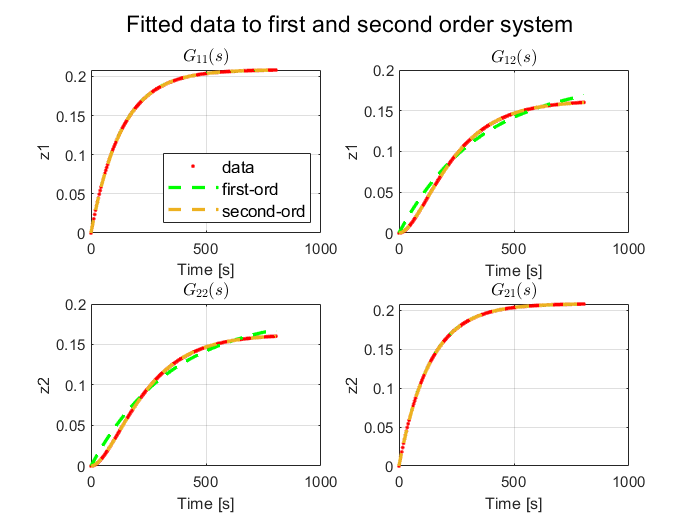

figure;
sgtitle('Fitted data to first and second order system')

subplot(2,2,1)
plot(tnew,y1datanew,'.r',tnew,y1fit,'--g',tnew,y1u1fitSO,'--','LineWidth',2); 
title('$G_{11}(s)$','interpreter','latex','fontsize',10)
xlabel('Time [s]'); ylabel('z1'); grid on;
legend('data','first-ord','second-ord','fontsize',10,'location','southeast');

subplot(2,2,2)
plot(tnew,y2datanew,'.r',tnew,y2fit,'--g',tnew,y2u1fitSO,'--','LineWidth',2)
title('$G_{12}(s)$','interpreter','latex','fontsize',10)
xlabel('Time [s]'); ylabel('z1'); grid on

subplot(2,2,3)
plot(tnew2,y2datanew2,'.r',tnew2,y2fit2,'--g',tnew2,y2u2fitSO2,'--','LineWidth',2)
title('$G_{22}(s)$','interpreter','latex','fontsize',10)
xlabel('Time [s]'); ylabel('z2'); grid on

subplot(2,2,4)
plot(tnew2,y1datanew2,'.r',tnew2,y1fit2,'--g',tnew2,y1u2fitSO2,'--','LineWidth',2)
title('$G_{21}(s)$','interpreter','latex','fontsize',10)
xlabel('Time [s]'); ylabel('z2'); grid on

# **Continuos Time transfer functions**


%*********************** Continuos Time transfer functions******************
% % from 2_ord
% %G11
num11 = model_y1u1(1);   %B11
den11 = conv([model_y1u1(2) 1],[model_y1u1(3) 1]); %A11

% G12
num12 = model_y1u2(1); % B12
den12 = conv([model_y1u2(2) 1],[model_y1u2(3) 1]); % A12
tau12 = 0;

% G21
num21 = model_y2u1(1); % B21
den21 = conv([model_y2u1(2) 1],[model_y2u1(3) 1]); % A21
tau21 = 0;

%G22
num22 = model_y2u2(1); % B22
den22 = conv([model_y2u2(2) 1],[model_y2u2(3) 1]); % A22

num=cell(2,2); den=cell(2,2); tau=zeros(2,2);


num{1,1}=num11; num{1,2}=num12;
num{2,1}=num21; num{2,2}=num22;

den{1,1}=den11; den{1,2}=den12;
den{2,1}=den21; den{2,2}=den22;

G11 = tf(num11,den11)

G11 =
 
            0.2087
  --------------------------
  1.786e04 s^2 + 267.3 s + 1
 
Continuous-time transfer function.



G12 =tf(num12,den12)

G12 =
 
            0.2087
  --------------------------
  1.786e04 s^2 + 267.3 s + 1
 
Continuous-time transfer function.



G21 = tf(num21,den21)

G21 =
 
            0.1622
  --------------------------
  1.561e04 s^2 + 252.4 s + 1
 
Continuous-time transfer function.



G22 = tf(num22,den22)

G22 =
 
            0.1622
  --------------------------
  1.561e04 s^2 + 252.4 s + 1
 
Continuous-time transfer function.




[w1, zeta1] = damp(G11)

w1 =     0.0075
    0.0075


zeta1 =      1
     1


Tau1 = 1./w1 

Tau1 =   133.6280
  133.6245


[z1,p1,k1] = zpkdata(G11)

z1 = 1×1 cell array
    {0×1 double}


p1 = 1×1 cell array
    {2×1 double}


k1 = 1.1690e-05

G11 = zpk(z1,p1,k1,'DisplayFormat','timeconstant')

G11 =
 
         0.20873
  ---------------------
  (1+133.6s) (1+133.6s)
 
Continuous-time zero/pole/gain model.




[w2, zeta2, p2] = damp(G12)

w2 =     0.0075
    0.0075


zeta2 =      1
     1


p2 =    -0.0075
   -0.0075


Tau2 = 1./w2 

Tau2 =   133.6280
  133.6245


[z2,p2,k2] = zpkdata(G12)

z2 = 1×1 cell array
    {0×1 double}


p2 = 1×1 cell array
    {2×1 double}


k2 = 1.1690e-05

G12 = zpk(z2,p2,k2,'DisplayFormat','timeconstant')

G12 =
 
         0.20873
  ---------------------
  (1+133.6s) (1+133.6s)
 
Continuous-time zero/pole/gain model.




[w3, zeta3, p3] = damp(G21)

w3 =     0.0069
    0.0092


zeta3 =      1
     1


p3 =    -0.0069
   -0.0092


Tau3 = 1./w3 

Tau3 =   143.9246
  108.4930


[z3,p3,k3] = zpkdata(G21)

z3 = 1×1 cell array
    {0×1 double}


p3 = 1×1 cell array
    {2×1 double}


k3 = 1.0387e-05

G21 = zpk(z3,p3,k3,'DisplayFormat','timeconstant')

G21 =
 
         0.1622
  ---------------------
  (1+108.5s) (1+143.9s)
 
Continuous-time zero/pole/gain model.




[w4, zeta4, p4] = damp(G22)

w4 =     0.0069
    0.0092


zeta4 =      1
     1


p4 =    -0.0069
   -0.0092


Tau4 = 1./w4

Tau4 =   143.9246
  108.4930


[z4,p4,k4] = zpkdata(G22)

z4 = 1×1 cell array
    {0×1 double}


p4 = 1×1 cell array
    {2×1 double}


k4 = 1.0387e-05

G22 = zpk(z4,p4,k4,'DisplayFormat','timeconstant')

G22 =
 
         0.1622
  ---------------------
  (1+108.5s) (1+143.9s)
 
Continuous-time zero/pole/gain model.



Nmax=100; tol=1e-8;
[Ad1,Bd1,Cd1,Dd1,sH1]=mimoctf2dss(num,den,tau,Ts,Nmax,tol)

Ad1 =     0.9967   -0.0270    0.0004    0.0000
    0.0270    0.9428    0.0003    0.0000
   -0.0011    0.0309    0.9640    0.0021
   -0.0002    0.0004   -0.0059    0.9739


Bd1 =    -0.0400   -0.0400
    0.0389    0.0389
   -0.0069   -0.0069
   -0.0002   -0.0002


Cd1 =    -0.0434   -0.0431   -0.0043    0.0001
   -0.0363   -0.0341    0.0066   -0.0002


Dd1 =      0     0
     0     0


sH1 =     0.1749
    0.0242
    0.0008
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


H1 = mimodss2dimpulse(Ad1,Bd1,Cd1,Dd1,Nmax) % markove parameter

H1 = H1(:,:,1) =

     0     0
     0     0


H1(:,:,2) =

   1.0e-04 *

    0.9167    0.9167
    0.8133    0.8133


H1(:,:,3) =

   1.0e-03 *

    0.2678    0.2678
    0.2371    0.2371


H1(:,:,4) =

   1.0e-03 *

    0.4335    0.4335
    0.3828    0.3828


H1(:,:,5) =

   1.0e-03 *

    0.5891    0.5891
    0.5191    0.5191


H1(:,:,6) =

   1.0e-03 *

    0.7352    0.7352
    0.6463    0.6463


H1(:,:,7) =

   1.0e-03 *

    0.8722    0.8722
    0.7649    0.7649


H1(:,:,8) =

    0.0010    0.0010
    0.0009    0.0009


H1(:,:,9) =

    0.0011    0.0011
    0.0010    0.0010


H1(:,:,10) =

    0.0012    0.0012
    0.0011    0.0011


H1(:,:,11) =

    0.0013    0.0013
    0.0012    0.0012


H1(:,:,12) =

    0.0014    0.0014
    0.0012    0.0012


H1(:,:,13) =

    0.0015    0.0015
    0.0013    0.0013


H1(:,:,14) =

    0.0016    0.0016
    0.0014    0.0014


H1(:,:,15) =

    0.0017    0.0017
    0.0015    0.0015


H1(:,:,16) =

    0.0018    0.0018
    0.0015    0.0015


H1(:,:,1

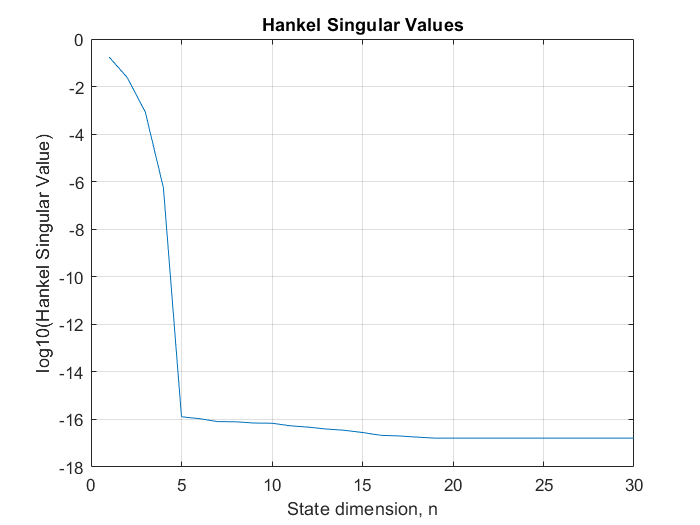


figure;
plot(log10(sH1));grid on;
title('Hankel Singular Values')
xlabel('State dimension, n');xlim([0 30])
ylabel('log10(Hankel Singular Value)')